# Solving the Reissner-Mindlin plate problem using sparse matrices and page-wise implementation

In this appendix it is demonstrated how to leverage [`sparse`](https://www.mathworks.com/help/matlab/ref/sparse.html)-matrices and [page-wise operations](https://blogs.mathworks.com/loren/2021/01/14/paged-matrix-functions/) in [MATLAB](https://www.mathworks.com/products/matlab.html)® to speed-up the computation, assembly and solution of the linear equation systems resulting from the discretization of the [Reissner-Mindlin plate](https://en.wikipedia.org/wiki/Mindlin%E2%80%93Reissner_plate_theory) *Boundary Value Problem* (BVP).

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Problem parameters**

### Geometric parameters

Plate's thickness [m]

propStr.t = 10^(-1);

X-coordinate of left corner [m]

X0 = 0;

X-coordinate of right corner [m]

XLx = 4;

Y-coordinate of left corner [m]

Y0 = 0;

Y-coordinate of right corner [m]

YLy = 1;

### Material paramerters

Distributed load [N/m^2]

propStr.pBar = -1e2;

Distributed moment around x-axis [N/m]

propStr.mxBar = 0;

Distributed moment around y-axis [N/m]

propStr.myBar = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = 0;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/2/(1 + propStr.nu);

Plate's stiffness [Nm]

propStr.D = propStr.E*propStr.t^3/12/(1 - propStr.nu^2);

Shear-correction factor

propStr.alpha = 5/6;

## Analytical solution using the Timoshenko beam formulation

Since the plate is rectangular, clamped on its one end while being subject to constant distributed vertical load its behavior is expected to resemble a beam aligned with the X-axis, whereas no effects are expected to take place along the Y-axis. The analytical solution for this problem using the shear-deformable Timoshenko beam formulation are in this case as follows

### Initialize auxiliary variables

syms wEx(X) betayEx(X) qxEx(X) Lsym psym Gsym Aqsym Esym Isym tsym alphaScf

### Analytical solution with respect to the vertical deflection

Set the analytical solution in terms of the vertical deflection field (Eq. (1) in the introduction):


$$w(X,Y) = \frac{1}{\alpha G A} \left( \overline{p} L X - \frac{\overline{p} X^2}{2} \right) - \frac{1}{EI} \left( - \frac{\overline{p} X^4}{24} + \frac{\overline{p} L X^3}{6} - \frac{\overline{p} L^2 X^2}{4} \right) \qquad (3)$$


namely:

wEx(X) = (psym*Lsym*X-psym*X^2/2)/Gsym/(Aqsym) - ...
    (-psym*X^4/24+psym*Lsym*X^3/6-psym*Lsym^2*X^2/4)/Esym/Isym;

### Analytical solution with respect to the transverse-shear forces

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)®


$$\beta(X,y) = \int_{0}^L - \frac{1}{\alpha G A}\overline{p} - \frac{\partial^2 w}{\partial x^2} \: \text{d}x  \qquad (4)$$


betayEx(X) = int(-1/(propStr.alpha*propStr.G*YLy*propStr.t)*propStr.pBar - ...
    diff(diff(wEx, X), X));

### Analytical solution with respect to the transverse-shear forces

Herein we are concerned with the resultant transverse-shear force component $q_x(X,Y) = \alpha G t \gamma_x = \alpha G t \overbrace{\left( \frac{\partial w}{\partial X} + \beta_y \right)}^{\gamma_x}$ because $q_y(X,Y)$ is identically zero across the plate due to the given setup. Resultant transverse-shear force component $q_x(X,Y) $ is given by:

qxEx(X) = alphaScf*Gsym*tsym*(diff(wEx(X), X, 1) + betayEx(X));

### Substitution of the known parameters in the analytical expression

wExSubs(X) = subs(wEx,{Lsym, psym, Gsym, Esym, Isym, Aqsym}, ...
    {XLx, propStr.pBar, propStr.G, propStr.E, YLy*(propStr.t^3)/12, ...
    propStr.alpha*YLy*propStr.t});
betayExSubs(X) = subs(betayEx, {Lsym, psym, Gsym, Esym, Isym, Aqsym}, ...
    {XLx, propStr.pBar, propStr.G, propStr.E, YLy*(propStr.t^3)/12, ...
    propStr.alpha*YLy*propStr.t});

## Verification of the the accuracy of the page-wise implementation

### **Quadrilateral mesh**

#### Choose number of elements in the mesh

Number of elements along the $X$-direction

numElx = 4;

Number of elements along the $Y$-direction

numEly = 2;

Total number of elements

numEl = numElx*numEly;

#### Mesh generation

[nodesX, nodesY] = generateQuadrilateralMesh(X0, XLx, Y0, YLy, numElx, numEly);

#### Rendering the mesh non-uniform

Check the following checkbox to render the mesh non-uniform **Note** This only works for `numElx = 4` and `numEly = 2` with the given values

isMeshNonUniform = false;
if isMeshNonUniform
    if numElx ~= 4 || numEly ~= 2
        error("Making the mesh non-uniform only works for numElx = 4 and numEly = 2")
    end

Displace node 2

    nodesY(2, 1) = nodesY(2, 1) + 0.08; % y

Displace node 5

    nodesX(2, 2) = nodesX(2, 2) + 0.08; % x
    nodesY(5, 1) = nodesY(5, 1) - 0.08; % y

Displace node 8

    nodesX(2, 3) = nodesX(2, 3) - 0.08; % x
    nodesY(8, 1) = nodesY(8, 1) + 0.08; % y

Displace node 11

    nodesX(2, 4) = nodesX(2, 4) + 0.08; % x
    nodesY(11, 1) = nodesY(11, 1) + 0.08; % x

Displace node 14

    nodesY(14, 1) = nodesY(14, 1) - 0.08; % x

end

### **Four-noded bilinear quadrilateral mesh**

#### Mesh generation

numNodesElQ1 = 4;
mshQ1 = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesElQ1);
numNodesQ1 = height(mshQ1.nodes);

#### Dirichlet boundary conditions for the mesh with the bilinear quadrilateral elements

[freeDOFsQ1, homDOFsQ1] = ...
    utilityFunctionsCantileverPlate.getFreeDOFsBilinearQuadrilateralMesh ...
    (numNodesQ1, numEly);

#### Mesh plot

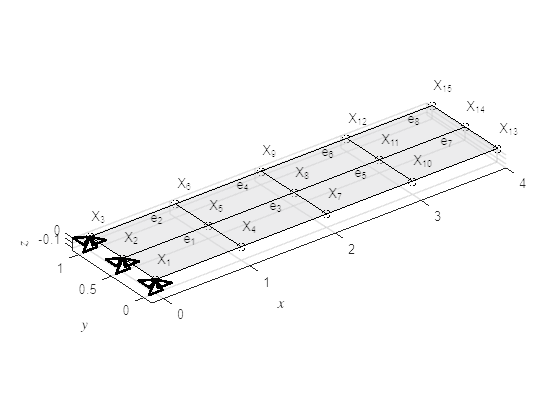

numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshQ1, numVertices, true);
hold on;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshQ1.nodes, homDOFsQ1);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, 'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", Interpreter="latex")
ylabel("$y$", Interpreter="latex")
zlabel("$z$", Interpreter="latex")

### **Nine-noded biquadratic quadrilateral mesh**

#### Mesh generation

numNodesElQ2 = 9;
[mshQ2, ~] = generateBiquadraticQuadrilateralMesh ...
    (numElx, numEly, nodesX, nodesY, mshQ1, numNodesElQ1, numNodesElQ2);
numNodesQ2 = height(mshQ2.nodes);

#### Dirichlet boundary conditions for the mesh with the biquadratic quadrilateral elements

[freeDOFsQ2, homDOFsQ2] = utilityFunctionsCantileverPlate.getFreeDOFsBiquadraticQuadrilateralMesh(numNodesQ1, numNodesQ2, numEly);

#### Mesh plot

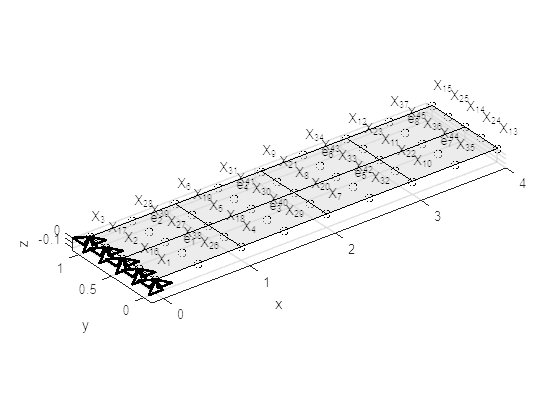

numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshQ2, numVertices, true);
hold on;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshQ2.nodes, homDOFsQ2);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, 'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("z")

### Master stiffness matrix and consistent nodal force vector with and without the page-wise implementation

#### Standard implementation for the two-dimenstional bilinear four-noded finite elements

computeStiffMatrixandForceVectorQ1 = ...
    @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
computeBasisFunctionsAndDerivsQ1 = ...
    @computeBilinearBasisFunctionsAndFirstDerivatives;
[KQ1, FQ1] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ1, computeBasisFunctionsAndDerivsQ1, computeStiffMatrixandForceVectorQ1, ...
    propStr);

#### Page-wise implementation using sparse matrices for the two-dimenstional bilinear four-noded finite elements

computeBasisFunctionsAndDerivsQ1 = ...
    @computeBilinearBasisFunctionsAndFirstDerivatives;
computeStiffMatrixandForceVectorQ1 = 'undefined';
[KQ1PageWise, FQ1PageWise] = ...
    computeMasterStiffMatrixandForceVctReissnerMindlinPlatePageWise ...
    (mshQ1, computeBasisFunctionsAndDerivsQ1, computeStiffMatrixandForceVectorQ1, ...
    propStr);

#### Standard implementation for the two-dimenstional biquadratic nine-noded finite elements

computeStiffMatrixandForceVectorQ2 = ...
    @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
computeBasisFunctionsAndDerivsQ2 = ...
    @computeBiquadraticBasisFunctionsAndFirstDerivatives;
[KQ2, FQ2] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ2, computeBasisFunctionsAndDerivsQ2, computeStiffMatrixandForceVectorQ2, ...
    propStr);

#### Page-wise implementation using sparse matrices for the two-dimenstional biquadratic nine-noded finite elements

computeBasisFunctionsAndDerivsQ2 = ...
    @computeBiquadraticBasisFunctionsAndFirstDerivatives;
computeStiffMatrixandForceVectorQ2 = 'undefined';
[KQ2PageWise, FQ2PageWise] = ...
    computeMasterStiffMatrixandForceVctReissnerMindlinPlatePageWise ...
    (mshQ2, computeBasisFunctionsAndDerivsQ2, computeStiffMatrixandForceVectorQ2, ...
    propStr);

### Solution of the discrete linear equation system

#### Standard implementation for the two-dimenstional bilinear four-noded finite elements

numDOFsQ1 = 2*numNodesQ1;
uQ1 = zeros(numDOFsQ1, 1);
uQ1(freeDOFsQ1, 1) = ...
    KQ1(freeDOFsQ1, freeDOFsQ1)\FQ1(freeDOFsQ1);

#### Page-wise implementation using sparse matrices for the two-dimenstional bilinear four-noded finite elements

uQ1PageWise = zeros(numDOFsQ1, 1);
uQ1PageWise(freeDOFsQ1, 1) = ...
    KQ1PageWise(freeDOFsQ1, freeDOFsQ1)\FQ1PageWise(freeDOFsQ1);

#### Standard implementation for the two-dimenstional biquadratic nine-noded finite elements

numDOFsQ2 = 2*numNodesQ2;
uQ2 = zeros(numDOFsQ2, 1);
uQ2(freeDOFsQ2, 1) = ...
    KQ2(freeDOFsQ2, freeDOFsQ2)\FQ2(freeDOFsQ2);

#### Page-wise implementation using sparse matrices for the two-dimenstional biquadratic nine-noded finite elements

uQ2PageWise = zeros(numDOFsQ2, 1);
uQ2PageWise(freeDOFsQ2, 1) = ...
    KQ2PageWise(freeDOFsQ2, freeDOFsQ2)\FQ2PageWise(freeDOFsQ2);

### Postprocessing the discrete solutions in terms of the vertical displacement field 

#### Standard implementation for the two-dimenstional bilinear four-noded finite elements

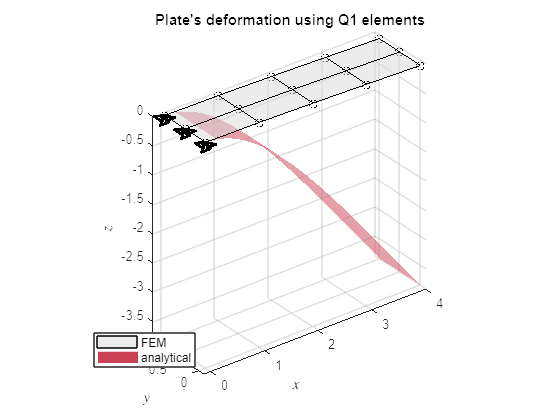

mshCurrQ1 = mshQ1;
scaling = 1;
mshCurrQ1.nodes(:, 3) = mshCurrQ1.nodes(:, 3) + scaling*uQ1(1:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1, numVertices, false);
hold on;
fsurf(wExSubs, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, FaceAlpha=0.5, ...
    LineStyle="none");
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshCurrQ1.nodes, homDOFsQ1);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, 'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
legend("FEM", "", "analytical", Location="best")
title("Plate's deformation using Q1 elements")

#### Page-wise implementation using sparse matrices for the two-dimenstional bilinear four-noded finite elements

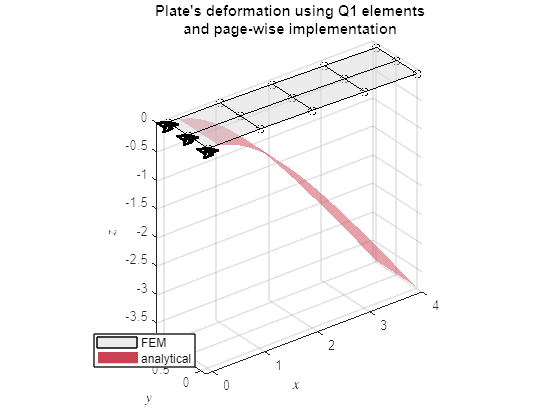

mshCurrQ1PageWise = mshQ1;
scaling = 1;
mshCurrQ1PageWise.nodes(:, 3) = mshCurrQ1PageWise.nodes(:, 3) + ...
    scaling*uQ1PageWise(1:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1PageWise, numVertices, false);
hold on;
fsurf(wExSubs, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, FaceAlpha=0.5, ...
    LineStyle="none");
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshCurrQ1PageWise.nodes, homDOFsQ1);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, 'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
legend("FEM", "", "analytical", Location="best")
title(["Plate's deformation using Q1 elements", "and page-wise implementation"])

#### Standard implementation for the two-dimenstional biquadratic nine-noded finite elements

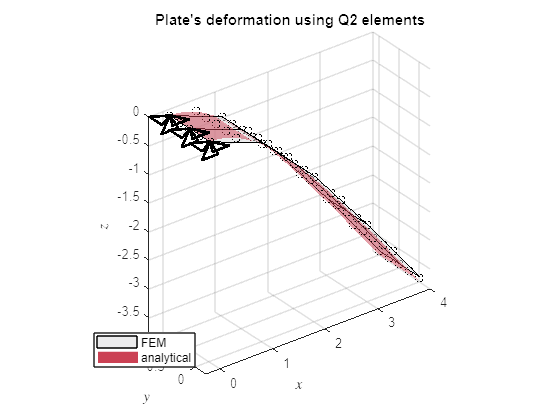

mshCurrQ2 = mshQ2;
scaling = 1;
mshCurrQ2.nodes(:, 3) = mshCurrQ2.nodes(:, 3) + ...
    scaling*uQ2(1:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ2, numVertices, false);
hold on;
fsurf(wExSubs, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, FaceAlpha=0.5, ...
    LineStyle="none");
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrQ2.nodes, homDOFsQ1);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, 'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
legend("FEM", "", "analytical", Location="best")
title("Plate's deformation using Q2 elements")

#### Page-wise implementation using sparse matrices for the two-dimenstional biquadratic nine-noded finite elements

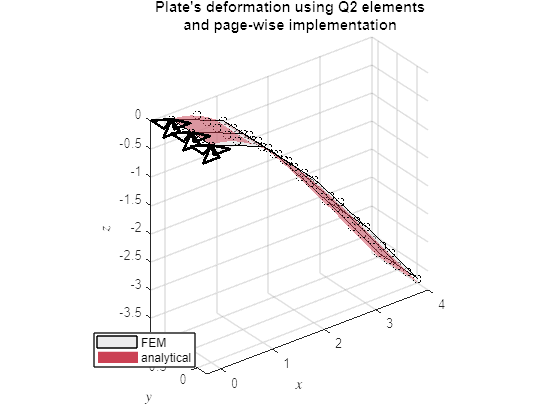

mshCurrQ2PageWise = mshQ2;
scaling = 1;
mshCurrQ2PageWise.nodes(:, 3) = mshCurrQ2PageWise.nodes(:, 3) + ...
    scaling*uQ2PageWise(1:3:end, 1);
numVertices = numel(mshQ2.nodes(:, 1));
plotMesh2d(mshCurrQ2PageWise, numVertices, false);
hold on;
fsurf(wExSubs, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, FaceAlpha=0.5, ...
    LineStyle="none");
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrQ2PageWise.nodes, homDOFsQ1);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, 'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
legend("FEM", "", "analytical", Location="best")
title(["Plate's deformation using Q2 elements", "and page-wise implementation"])

## Runtime performance using sparse matrices and page-wise implementation of the bilinear four-noded finite elements

### Initialize auxiliary variables

numRef = 50;
stp = 7;
runtimePerformanceQ1 = zeros(ceil(numRef/stp), 2);
numDOFsQ1 = zeros(ceil(numRef/stp), 1);

### Loop over all the refinement levels

for ii = 1:stp:numRef

#### Generation of the the finite element mesh

Number of elements along the $X$-direction

    numElxRef = 4*ii;

Number of elements along the $Y$-direction

    numElyRef = 1*ii;

Total number of elements

    numElQ1 = numElxRef*numElyRef; % total number of elements    

Mesh generation

    [nodesXRef, nodesYRef] = ...
        generateQuadrilateralMesh(X0, XLx, Y0, YLy, numElxRef, numElyRef);
    mshQ1Ref = generateBilinearQuadrilateralMesh ...
        (numElxRef, numElyRef, numElQ1, nodesXRef, nodesYRef, numNodesElQ1);
    numNodesQ1Ref = height(mshQ1Ref.nodes);
    numDOFsQ1(ceil(ii/stp), 1) = 3*numNodesQ1Ref;

#### Definition of the Dirichlet boundary conditions

    [freeDOFsQ1Ref, ~] = ...
        utilityFunctionsCantileverPlate.getFreeDOFsBilinearQuadrilateralMesh ...
        (numNodesQ1Ref, numElyRef);

#### Solution of the discrete problem using the standard Finite Element implementation

... starting the timer

    tic;

... computing of the stiffness matrix and consistent nodal force vector for the one-dimensional two-noded linear mesh

    computeStiffMatrixandForceVectorQ1 = ...
        @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
    computeBasisFunctionsAndDerivsQ1 = ...
        @computeBilinearBasisFunctionsAndFirstDerivatives;
    [K, F] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
        (mshQ1Ref, computeBasisFunctionsAndDerivsQ1, computeStiffMatrixandForceVectorQ1, ...
        propStr);

... solving the discrete linear equation system

    [~] = K(freeDOFsQ1Ref, freeDOFsQ1Ref)\F(freeDOFsQ1Ref);

... stopping the timer

    runtimePerformanceQ1(ceil(ii/stp), 1) = toc;

#### Solution of the discrete problem using the page-wise Finite Element implementation with sparse matrices

... starting the timer

    tic;

... computing of the stiffness matrix and consistent nodal force vector for the one-dimensional two-noded linear mesh

    computeBasisFunctionsAndDerivsQ1 = ...
        @computeBilinearBasisFunctionsAndFirstDerivatives;
    computeStiffMatrixandForceVectorQ1 = 'undefined';
    [K, F] = computeMasterStiffMatrixandForceVctReissnerMindlinPlatePageWise ...
        (mshQ1Ref, computeBasisFunctionsAndDerivsQ1, computeStiffMatrixandForceVectorQ1, ...
        propStr);

... solving the discrete linear equation system

    [~] = K(freeDOFsQ1Ref, freeDOFsQ1Ref)\F(freeDOFsQ1Ref);

... stopping the timer

    runtimePerformanceQ1(ceil(ii/stp), 2) = toc;

end

### Display of the runtime performance comparison between the standard and the page-wise implementation

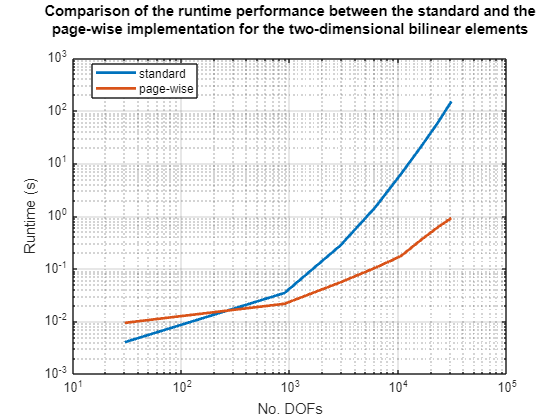

loglog(numDOFsQ1, runtimePerformanceQ1, LineWidth=2);
legend("standard", "page-wise", Location="best")
grid on;
xlabel("No. DOFs")
ylabel("Runtime (s)")
title(["Comparison of the runtime performance between the standard and the", ...
    "page-wise implementation for the two-dimensional bilinear elements", ""])

## Runtime performance using sparse matrices and page-wise implementation of the biquadratic nine-noded finite elements

### Initialize auxiliary variables

numRef = 31;
stp = 5;
runtimePerformanceQ2 = zeros(ceil(numRef/stp), 2);
numDOFsQ2 = zeros(ceil(numRef/stp), 1);

### Loop over all the refinement levels

for ii = 1:stp:numRef

#### Generation of the the finite element mesh

Number of elements along the $X$-direction

    numElxRef = 4*ii;

Number of elements along the $Y$-direction

    numElyRef = 1*ii;

Total number of elements

    numElQ2 = numElxRef*numElyRef;

Mesh generation

    [nodesXRef, nodesYRef] = ...
        generateQuadrilateralMesh(X0, XLx, Y0, YLy, numElxRef, numElyRef);
    mshQ1Ref = generateBilinearQuadrilateralMesh ...
        (numElxRef, numElyRef, numElQ2, nodesXRef, nodesYRef, numNodesElQ1);
    numNodesQ1Ref = height(mshQ1Ref.nodes);
    [mshQ2Ref, ~] = generateBiquadraticQuadrilateralMesh ...
        (numElxRef, numElyRef, nodesXRef, nodesYRef, mshQ1Ref, numNodesElQ1, numNodesElQ2);
    numNodesQ2Ref = height(mshQ2Ref.nodes);
    numDOFsQ2(ceil(ii/stp), 1) = 3*numNodesQ2Ref;

#### Definition of the Dirichlet boundary conditions

    [freeDOFsQ2Ref, ~] = ...
        utilityFunctionsCantileverPlate.getFreeDOFsBiquadraticQuadrilateralMesh ...
        (numNodesQ1Ref, numNodesQ2Ref, numElyRef);    

#### Solution of the discrete problem using the standard Finite Element implementation

... starting the timer

    tic;

... computing of the stiffness matrix and consistent nodal force vector for the one-dimensional two-noded linear mesh

    computeStiffMatrixandForceVectorQ2 = ...
        @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
    computeBasisFunctionsAndDerivsQ2 = ...
        @computeBiquadraticBasisFunctionsAndFirstDerivatives;
    [K, F] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
        (mshQ2Ref, computeBasisFunctionsAndDerivsQ2, computeStiffMatrixandForceVectorQ2, ...
        propStr);

... solving the discrete linear equation system

    [~] = K(freeDOFsQ2Ref, freeDOFsQ2Ref)\F(freeDOFsQ2Ref);

... stopping the timer

    runtimePerformanceQ2(ceil(ii/stp), 1) = toc;

#### Solution of the discrete problem using the page-wise Finite Element implementation with sparse matrices

... starting the timer

    tic;

... computing of the stiffness matrix and consistent nodal force vector for the one-dimensional two-noded linear mesh

    computeBasisFunctionsAndDerivsQ2 = ...
        @computeBiquadraticBasisFunctionsAndFirstDerivatives;
    computeStiffMatrixandForceVectorQ2 = 'undefined';
    [K, F] = computeMasterStiffMatrixandForceVctReissnerMindlinPlatePageWise ...
        (mshQ2Ref, computeBasisFunctionsAndDerivsQ2, computeStiffMatrixandForceVectorQ2, ...
        propStr);

... solving the discrete linear equation system

    [~] = K(freeDOFsQ2Ref, freeDOFsQ2Ref)\F(freeDOFsQ2Ref);

... stopping the timer

    runtimePerformanceQ2(ceil(ii/stp), 2) = toc;

end

### Display of the runtime performance comparison between the standard and the page-wise implementation

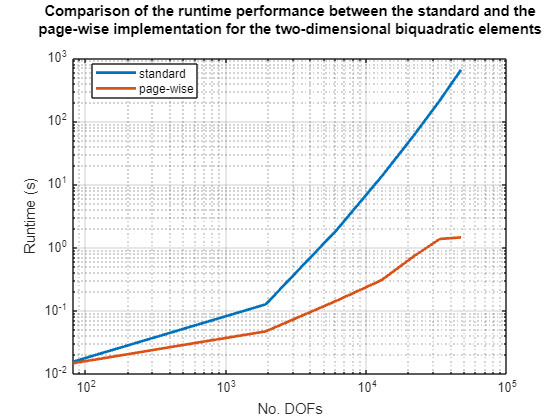

loglog(numDOFsQ2, runtimePerformanceQ2, LineWidth=2);
legend("standard", "page-wise", Location="best")
grid on;
xlabel("No. DOFs")
ylabel("Runtime (s)")
title(["Comparison of the runtime performance between the standard and the", ...
    "page-wise implementation for the two-dimensional biquadratic elements", ""])

## References

[[1] cane Multiphysics; 2023](https://github.com/andreas-apostolatos/cane)